show feature points

I = imread('cameraman.tif');
pointsS = detectSURFFeatures(I)

pointsS =   180×1 SURFPoints array with properties:

              Scale: [180×1 single]
    SignOfLaplacian: [180×1 int8]
        Orientation: [180×1 single]
           Location: [180×2 single]
             Metric: [180×1 single]
              Count: 180


pointsH = detectHarrisFeatures(I)

pointsH =   184×1 cornerPoints array with properties:

    Location: [184×2 single]
      Metric: [184×1 single]
       Count: 184


display

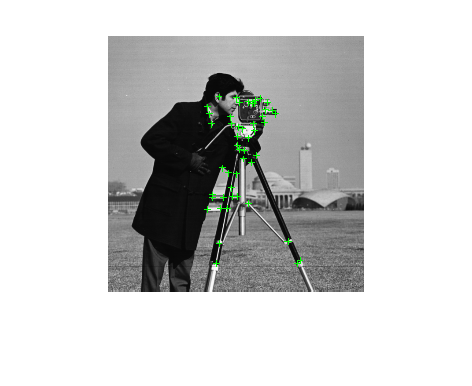

imshow(I); hold on;
plot(pointsH.selectStrongest(50));

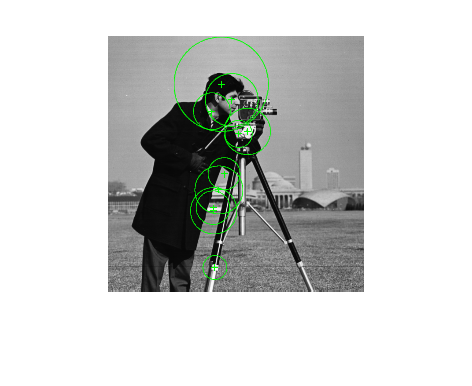

figure();imshow(I); hold on;
plot(pointsS.selectStrongest(10));